slack_1 = flow_num * 0.7

slack_1 = 7.6384e+06

slack_2 = spread_sum * 0.7

slack_2 = 1.1456e+07


obj_vec = size_mat(:,2).*size_mat(:,2)/bkt_num;
x_len = size(size_mat,1)

x_len = 48


global HLL_dist;
global aggr_dist;
global dist_arr_size;
dist_arr_size = 500;
HLL_dist = zeros(1,dist_arr_size);
ptr = 1

ptr = 1

for i = 1:dist_arr_size
    intval_lb = 10 * (i-1);
    intval_ub = 10 * i - 1;
    intval_sum = 0;
    while ptr <= size(HLL_val_dist,1) && HLL_val_dist(ptr,1) <= intval_ub
        intval_sum = intval_sum + HLL_val_dist(ptr,2);
        ptr = ptr + 1;
    end
    HLL_dist(1,i) = intval_sum;
end

objconstr = @generate_dist%@(X)( (dot(obj_vec,X) - Var_ )^2 + sum( (X(1,2:x_len)./(X(1,1:x_len-1)+0.001)).^20 ));

objconstr = 包含以下值的 function_handle :
    @generate_dist


A = ones(1 , size(size_mat,1));
b = [flow_num + slack_1];
A = [A;-A];
b = [b;slack_1 - flow_num];
A = [A;size_mat(:,2).'];
b = [b;spread_sum + slack_2];
A = [A;-1*size_mat(:,2).'];
b = [b;slack_2 - spread_sum];
intcon = [1:1:size(size_mat,1)];
lb = zeros(size(size_mat,1),1);
lb(1:14,1) = 2

lb =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


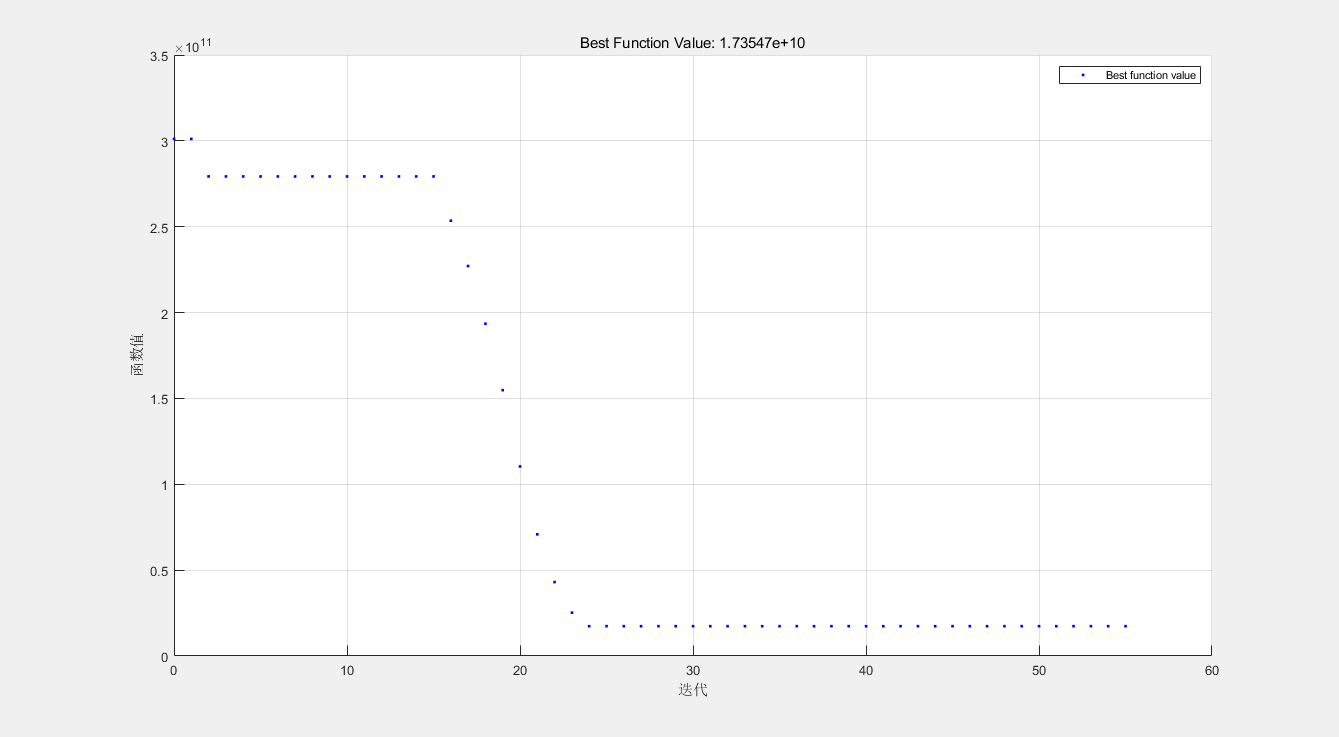

surrogateopt found a feasible solution.
surrogateopt stopped because no new feasible points were found on which the function can be evaluated.


X =      5413056     1790026     1193350      357125           2           2           2           2           2           2           2           2           2           2           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0          10        3685        2632        2046


ub = spread_sum./size_mat(:,2);
global ansarr;
ansarr = [];

global gaus_arr;
diata = 1.05/sqrt(32);
gaus_arr = randn(1,300000) * sqrt(diata);
%figure(1)
X = surrogateopt(objconstr,lb,ub,intcon,A,b)